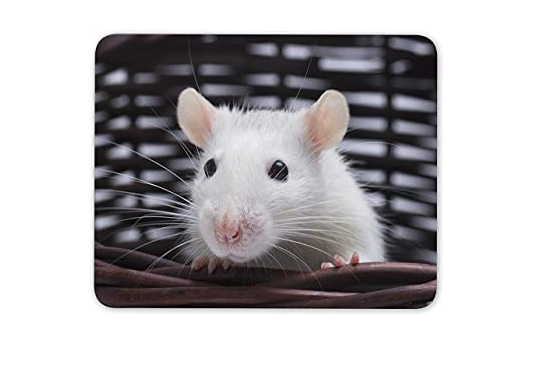

clc; clear; close all

img=imread('Test_rat_image.jpg');
imshow(img)

I=rgb2gray(img);

%I_sobel=edge(I,'Sobel');
[I_test, threshold]=edge(I,'Canny');

Threshold

threshold

threshold =     0.0688    0.1719


I_edge=edge(I,'Canny',4* threshold);



Eye isolation

se90=strel('line',3,90);
se0=strel('line',3,0);
I_dilate=imdilate(I_edge,[se90 se0]);

I_fill=imfill(I_dilate,'holes');

I_erode=imerode(I_fill,[se90 se0]);
I_erode=imerode(I_erode,[se90 se0])

I_erode = 287×355 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

I_clear=imclearborder(I_erode);

I_final=labeloverlay(img,I_clear)

I_final = 287×355×3 uint8 array
I_final(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   253   253   254   255   255   255   255   254   253   254   255   255   255   255   255   255   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   255   253   254   255   255   255   255   255   255   252   253   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   253   253   253   253   253   253   253   251   251   251   251   251   251   251   251   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254  

Final images

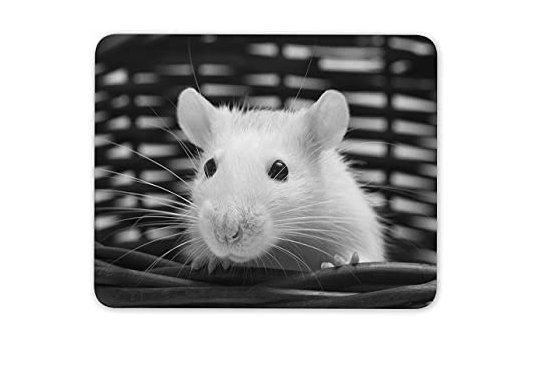

imshow(I)

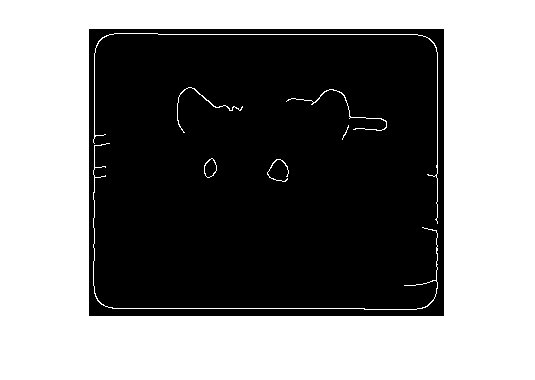

imshow(I_edge)

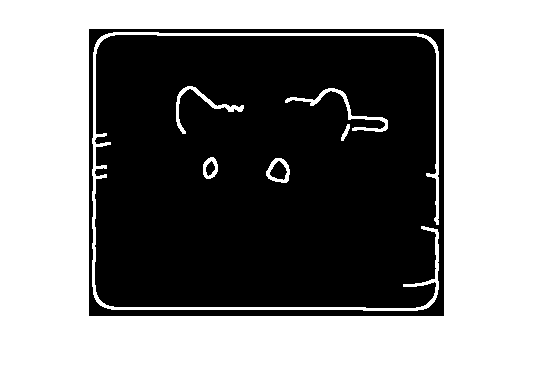


imshow(I_dilate)

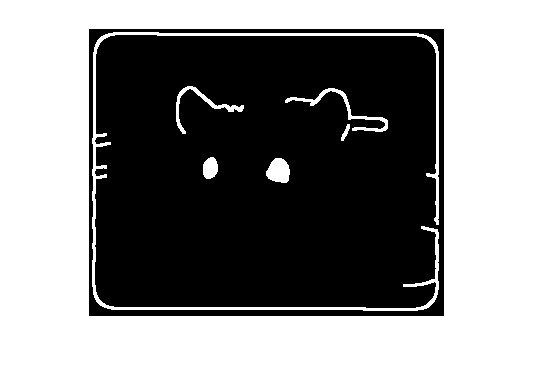

imshow(I_fill)

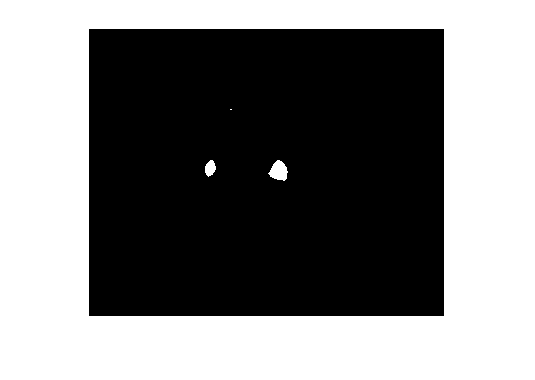

imshow(I_erode)

imshow(I_clear)

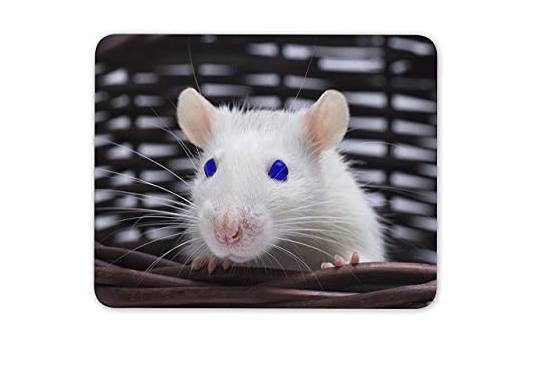


imshow(I_final)

Calculation of eye's area (biggest on image)

region=regionprops(I_clear)

region = 3×1 struct array with fields:
    Area
    Centroid
    BoundingBox


x=find(region==max(area))

Cannot find an exact (case-sensitive) match for 'Area'

The closest match is: area in C:\Program Files\MATLAB\R2020a\toolbox\matlab\specgraph\area.m